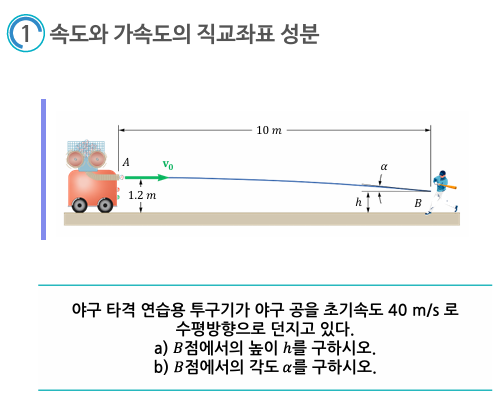

**주어진 정보:**

- 초기 속도 $v_0 = 40 \, \text{m/s}$(수평 방향)

- A점에서 공의 높이$y_0 = 1.2 \, \text{m}$

- A점에서 B점까지의 수평 거리 $x = 10 \, \text{m}$

- 중력 가속도 $g = 9.81 \, \text{m/s}^2$

**a) B****점에서의 높이 h****를 구하는 방법:**

수평 방향으로 던져진 물체의 수직 위치는 시간에 따라 변하며, 그 식은 다음과 같습니다:


$$y(t) = y_0 - \frac{1}{2} g t^2$$


수평 방향의 움직임은 속도가 일정하므로 시간 ttt에 따라 수평 위치$x(t)$는:


$$x(t) = v_0 t$$


수평 거리 $x = 10 \, \text{m}$에 대해 시간을 구하려면:

$t = \frac{x}{v_0}$�

이를 통해 t를 구한 후, 수직 위치 $y(t)$에서 B점의 높이 h를 계산할 수 있습니다.

**b) B****점에서의 각도 **$\alpha$**를 구하는 방법:**

각도 $\alpha$는 공의 속도 벡터가 지면과 이루는 각도입니다. 이 각도는 수직 속도와 수평 속도를 이용해 계산할 수 있습니다. 수직 속도는 시간 t에 따른 속도로, 다음 식을 사용합니다:


$$v_y(t) = -g tv$$


수평 속도는 일정하므로:

$v_x = v_0$�

따라서 각도 $\alpha$는:

$\tan(\alpha) = \frac{v_y(t)}{v_x}$�

위 공식을 사용하여 $\alpha$를 구할 수 있습니다.

% 주어진 값
v0 = 40;   % 초기 속도 (m/s)
y0 = 1.2;  % 초기 높이 (m)
g = 9.81;  % 중력 가속도 (m/s^2)
x_B = 10;  % A에서 B까지의 수평 거리 (m)

% a) B점에서의 높이 h 계산
t_B = x_B / v0;  % B점에서의 시간
h_B = y0 - (1/2) * g * t_B^2;  % B점에서의 높이

% b) B점에서의 각도 alpha 계산
vy_B = -g * t_B;  % B점에서의 수직 속도
vx_B = v0;        % 수평 속도는 일정
alpha_B = atan2(vy_B, vx_B) * 180 / pi;  % 각도 (도 단위로 변환)

% 결과 출력
fprintf('B점에서의 높이 h: %.2f m\n', h_B);

B점에서의 높이 h: 0.89 m


fprintf('B점에서의 각도 alpha: %.2f 도\n', alpha_B);

B점에서의 각도 alpha: -3.51 도


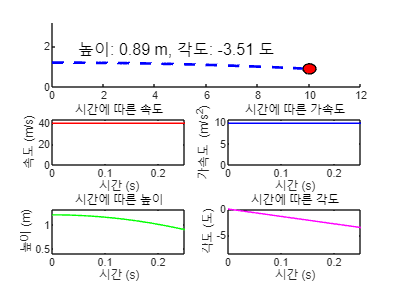


% 포물선 궤적 애니메이션
t_vals = linspace(0, t_B, 100);
x_vals = v0 * t_vals;
y_vals = y0 - (1/2) * g * t_vals.^2;
vy_vals = -g * t_vals;
v_vals = sqrt(v0^2 + vy_vals.^2);  % 총 속도
a_vals = g * ones(size(t_vals));  % 가속도는 일정함
alpha_vals = atan2(vy_vals, v0) * 180 / pi;  % 각도 계산

% 애니메이션 준비
figure;

% 애니메이션 부분
subplot(3, 2, [1, 2]);  % 상단에 애니메이션
hold on;
xlim([0, 12]);  % x축 범위
ylim([0, y0 + 2]);  % y축 범위

% 포물선 궤적 그리기
plot(x_vals, y_vals, 'b--', 'LineWidth', 2);

% 공 그래픽 생성
ball = rectangle('Position', [0, y0, 0.5, 0.5], 'Curvature', [1, 1], 'FaceColor', 'r');

% 높이 및 각도 정보 텍스트 추가
info_text = text(1, 1.8, sprintf('높이: %.2f m, 각도: %.2f 도', y0, 0), 'FontSize', 12, 'Color', 'k');

% 그래프 설정
subplot(3, 2, 3);  % 속도 그래프
h_velocity = plot(t_vals(1), v_vals(1), 'r');  % 초기값 설정
xlim([0 , t_B]);  % 시간 축 설정
ylim([0, max(v_vals) * 1.1]);  % 속도 그래프의 y축 범위 설정
xlabel('시간 (s)');
ylabel('속도 (m/s)');
title('시간에 따른 속도');

subplot(3, 2, 4);  % 가속도 그래프
h_acceleration = plot(t_vals(1), a_vals(1), 'b');  % 초기값 설정
xlim([0, t_B]);  % 시간 축 설정
ylim([0, g * 1.1]);  % 가속도 그래프의 y축 범위 설정
xlabel('시간 (s)');
ylabel('가속도 (m/s^2)');
title('시간에 따른 가속도');

subplot(3, 2, 5);  % 높이 그래프
h_height = plot(t_vals(1), y_vals(1), 'g');  % 초기값 설정
xlim([0, t_B]);  % 시간 축 설정
ylim([min(y_vals) - 0.5, max(y_vals) * 1.1]);  % 높이 그래프의 y축 범위 설정
xlabel('시간 (s)');
ylabel('높이 (m)');
title('시간에 따른 높이');

subplot(3, 2, 6);  % 각도 그래프
h_angle = plot(t_vals(1), alpha_vals(1), 'm');  % 초기값 설정
xlim([0, t_B]);  % 시간 축 설정
ylim([min(alpha_vals) - 5, max(alpha_vals) * 1.1]);  % 각도 그래프의 y축 범위 설정
xlabel('시간 (s)');
ylabel('각도 (도)');
title('시간에 따른 각도');

% 애니메이션 루프
for i = 1:length(t_vals)
    % 공 위치 업데이트
    set(ball, 'Position', [x_vals(i)-0.25, y_vals(i)-0.25, 0.5, 0.5]);  % 공 위치 업데이트
    
    % 텍스트 업데이트 (높이 및 각도)
    set(info_text, 'String', sprintf('높이: %.2f m, 각도: %.2f 도', y_vals(i), alpha_vals(i)));
    
    % 그래프 업데이트
    set(h_velocity, 'XData', t_vals(1:i), 'YData', v_vals(1:i));  % 속도 그래프 업데이트
    set(h_acceleration, 'XData', t_vals(1:i), 'YData', a_vals(1:i));  % 가속도 그래프 업데이트
    set(h_height, 'XData', t_vals(1:i), 'YData', y_vals(1:i));  % 높이 그래프 업데이트
    set(h_angle, 'XData', t_vals(1:i), 'YData', alpha_vals(1:i));  % 각도 그래프 업데이트
    
    % 화면 강제 갱신
    drawnow;
    
    pause(0.05);  % 애니메이션 속도 조절
end

hold off;

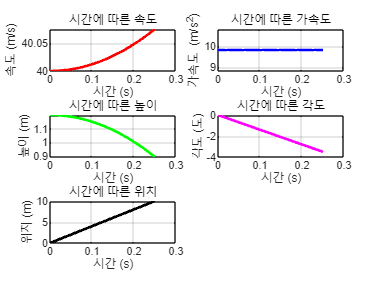

% 주어진 값
v0 = 40;   % 초기 속도 (m/s)
y0 = 1.2;  % 초기 높이 (m)
g = 9.81;  % 중력 가속도 (m/s^2)
x_B = 10;  % A에서 B까지의 수평 거리 (m)

% B점에서의 시간 계산
t_B = x_B / v0;

% 시간 벡터 생성
t_vals = linspace(0, t_B, 100);  % 0에서 t_B까지 100개의 점으로 시간 구간 설정

% 물리량 계산
x_vals = v0 * t_vals;                          % 위치 (수평 거리)
y_vals = y0 - (1/2) * g * t_vals.^2;           % 높이
vy_vals = -g * t_vals;                         % 수직 속도
v_vals = sqrt(v0^2 + vy_vals.^2);              % 총 속도
a_vals = g * ones(size(t_vals));               % 가속도는 일정함
alpha_vals = atan2(vy_vals, v0) * 180 / pi;    % 각도 (라디안에서 도 단위로 변환)

% 1. 시간에 따른 속도 그래프
figure;
subplot(3, 2, 1);
plot(t_vals, v_vals, 'r', 'LineWidth', 2);
xlabel('시간 (s)');
ylabel('속도 (m/s)');
title('시간에 따른 속도');
grid on;

% 2. 시간에 따른 가속도 그래프
subplot(3, 2, 2);
plot(t_vals, a_vals, 'b', 'LineWidth', 2);
xlabel('시간 (s)');
ylabel('가속도 (m/s^2)');
title('시간에 따른 가속도');
grid on;

% 3. 시간에 따른 높이 그래프
subplot(3, 2, 3);
plot(t_vals, y_vals, 'g', 'LineWidth', 2);
xlabel('시간 (s)');
ylabel('높이 (m)');
title('시간에 따른 높이');
grid on;

% 4. 시간에 따른 각도 그래프
subplot(3, 2, 4);
plot(t_vals, alpha_vals, 'm', 'LineWidth', 2);
xlabel('시간 (s)');
ylabel('각도 (도)');
title('시간에 따른 각도');
grid on;

% 5. 시간에 따른 위치(수평 거리) 그래프
subplot(3, 2, 5);
plot(t_vals, x_vals, 'k', 'LineWidth', 2);
xlabel('시간 (s)');
ylabel('위치 (m)');
title('시간에 따른 위치');
grid on;

% 그래프 레이아웃 조정
subplot(3, 2, 6);
axis off;  % 빈 공간으로 두기

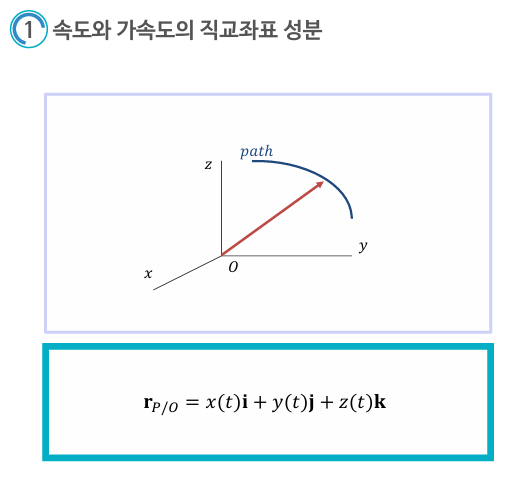

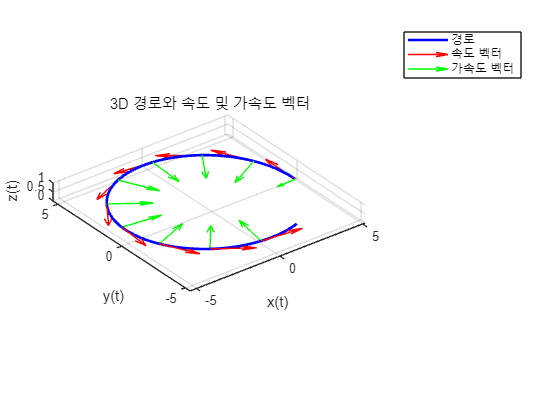

% 시간 변수 정의
t = linspace(0, 10, 100);  % 0에서 10초까지의 시간 (100개의 값)

% x(t), y(t), z(t) 위치 함수 정의 (예시)
x_t = 5 * cos(0.5 * t);  % 예시로 원형 경로
y_t = 5 * sin(0.5 * t);  % 예시로 원형 경로
z_t = 0.1 * t;           % z 방향으로 선형 증가

% 속도 v(t) 정의 (위치의 미분)
vx_t = gradient(x_t, t);  % x(t)의 미분 (속도 성분 x 방향)
vy_t = gradient(y_t, t);  % y(t)의 미분 (속도 성분 y 방향)
vz_t = gradient(z_t, t);  % z(t)의 미분 (속도 성분 z 방향)

% 가속도 a(t) 정의 (속도의 미분)
ax_t = gradient(vx_t, t);  % x 방향 가속도
ay_t = gradient(vy_t, t);  % y 방향 가속도
az_t = gradient(vz_t, t);  % z 방향 가속도

% 3D 경로 플롯
figure;
plot3(x_t, y_t, z_t, 'b', 'LineWidth', 2);  % 경로 그리기
hold on;
quiver3(x_t(1:10:end), y_t(1:10:end), z_t(1:10:end), vx_t(1:10:end), vy_t(1:10:end), vz_t(1:10:end), 0.5, 'r');  % 속도 벡터
quiver3(x_t(1:10:end), y_t(1:10:end), z_t(1:10:end), ax_t(1:10:end), ay_t(1:10:end), az_t(1:10:end), 0.5, 'g');  % 가속도 벡터
xlabel('x(t)');
ylabel('y(t)');
zlabel('z(t)');
title('3D 경로와 속도 및 가속도 벡터');
grid on;
axis equal;

legend('경로', '속도 벡터', '가속도 벡터');

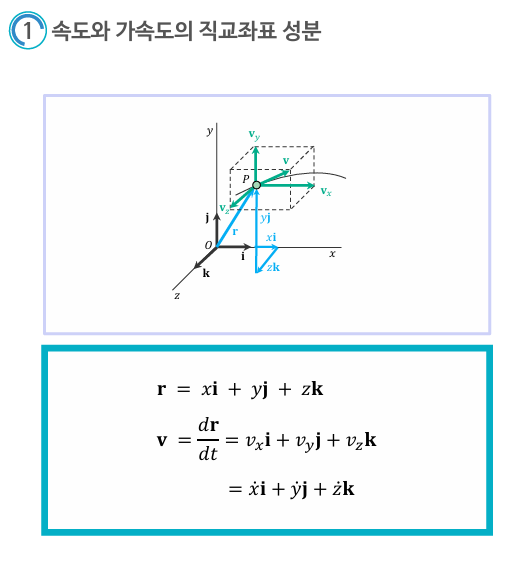

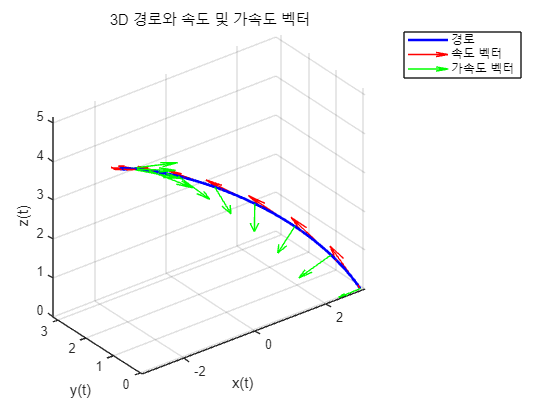

% 시간 벡터
t = linspace(0, 10, 100);  % 0에서 10까지의 시간

% 위치 벡터 r(t) 정의 (예시)
x_t = 3 * cos(0.3 * t);  % x(t): 코사인 함수 예시
y_t = 3 * sin(0.3 * t);  % y(t): 사인 함수 예시
z_t = 0.5 * t;           % z(t): 선형 증가

% 속도 벡터 v(t) = dr/dt
vx_t = gradient(x_t, t);  % x 방향 속도
vy_t = gradient(y_t, t);  % y 방향 속도
vz_t = gradient(z_t, t);  % z 방향 속도

% 가속도 벡터 a(t) = dv/dt
ax_t = gradient(vx_t, t);  % x 방향 가속도
ay_t = gradient(vy_t, t);  % y 방향 가속도
az_t = gradient(vz_t, t);  % z 방향 가속도

% 3D 경로 그리기
figure;
plot3(x_t, y_t, z_t, 'b', 'LineWidth', 2);  % 경로
hold on;

% 속도 벡터 그리기
quiver3(x_t(1:10:end), y_t(1:10:end), z_t(1:10:end), vx_t(1:10:end), vy_t(1:10:end), vz_t(1:10:end), 0.5, 'r');

% 가속도 벡터 그리기
quiver3(x_t(1:10:end), y_t(1:10:end), z_t(1:10:end), ax_t(1:10:end), ay_t(1:10:end), az_t(1:10:end), 0.5, 'g');

% 그래프 레이블 및 설정
xlabel('x(t)');
ylabel('y(t)');
zlabel('z(t)');
title('3D 경로와 속도 및 가속도 벡터');
grid on;
axis equal;
legend('경로', '속도 벡터', '가속도 벡터');

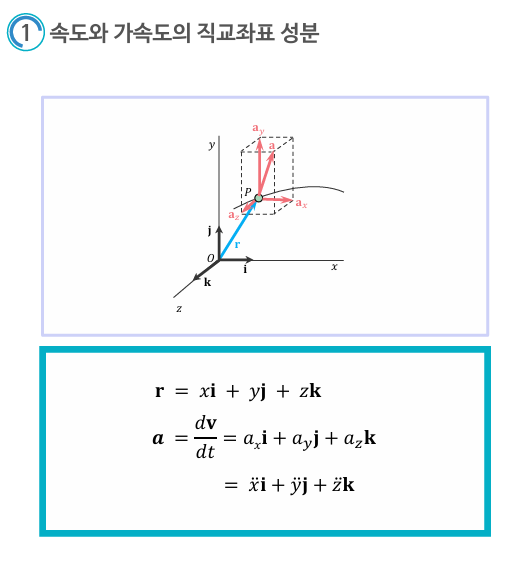

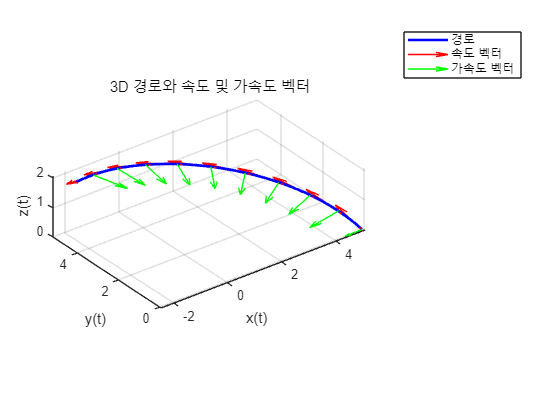

% 시간 설정
t = linspace(0, 10, 100);  % 시간 벡터 (0에서 10초까지 100개 점)

% 위치 r(t) 설정 (예시로 원형 궤도 + z 방향 선형 이동)
x_t = 5 * cos(0.2 * t);  % x(t): 코사인 함수
y_t = 5 * sin(0.2 * t);  % y(t): 사인 함수
z_t = 0.2 * t;           % z(t): 선형 증가

% 속도 v(t) = dr/dt
vx_t = gradient(x_t, t);  % x 방향 속도
vy_t = gradient(y_t, t);  % y 방향 속도
vz_t = gradient(z_t, t);  % z 방향 속도

% 가속도 a(t) = dv/dt
ax_t = gradient(vx_t, t);  % x 방향 가속도
ay_t = gradient(vy_t, t);  % y 방향 가속도
az_t = gradient(vz_t, t);  % z 방향 가속도

% 3D 경로 그리기
figure;
plot3(x_t, y_t, z_t, 'b', 'LineWidth', 2);  % 경로
hold on;

% 속도 벡터 그리기 (파란색 화살표)
quiver3(x_t(1:10:end), y_t(1:10:end), z_t(1:10:end), vx_t(1:10:end), vy_t(1:10:end), vz_t(1:10:end), 0.5, 'r');

% 가속도 벡터 그리기 (빨간색 화살표)
quiver3(x_t(1:10:end), y_t(1:10:end), z_t(1:10:end), ax_t(1:10:end), ay_t(1:10:end), az_t(1:10:end), 0.5, 'g');

% 그래프 레이블 및 설정
xlabel('x(t)');
ylabel('y(t)');
zlabel('z(t)');
title('3D 경로와 속도 및 가속도 벡터');
grid on;
axis equal;
legend('경로', '속도 벡터', '가속도 벡터');
hold off;

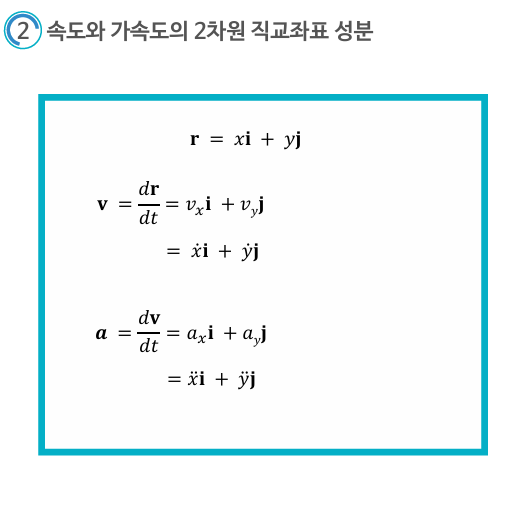

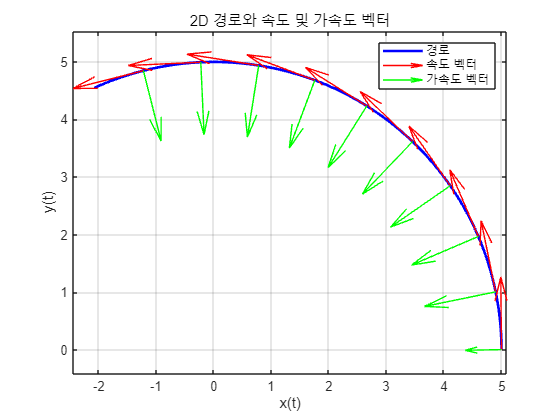

% 시간 설정
t = linspace(0, 10, 100);  % 0에서 10초까지 100개의 점

% 2D 위치 r(t) 설정 (예시: 원형 경로)
x_t = 5 * cos(0.2 * t);  % x(t): 코사인 함수
y_t = 5 * sin(0.2 * t);  % y(t): 사인 함수

% 속도 v(t) = dr/dt
vx_t = gradient(x_t, t);  % x 방향 속도
vy_t = gradient(y_t, t);  % y 방향 속도

% 가속도 a(t) = dv/dt
ax_t = gradient(vx_t, t);  % x 방향 가속도
ay_t = gradient(vy_t, t);  % y 방향 가속도

% 2D 경로 그리기
figure;
plot(x_t, y_t, 'b', 'LineWidth', 2);  % 경로
hold on;

% 속도 벡터 그리기
quiver(x_t(1:10:end), y_t(1:10:end), vx_t(1:10:end), vy_t(1:10:end), 0.5, 'r');  % 속도 벡터

% 가속도 벡터 그리기
quiver(x_t(1:10:end), y_t(1:10:end), ax_t(1:10:end), ay_t(1:10:end), 0.5, 'g');  % 가속도 벡터

% 그래프 설정
xlabel('x(t)');
ylabel('y(t)');
title('2D 경로와 속도 및 가속도 벡터');
grid on;
axis equal;
legend('경로', '속도 벡터', '가속도 벡터');
hold off;

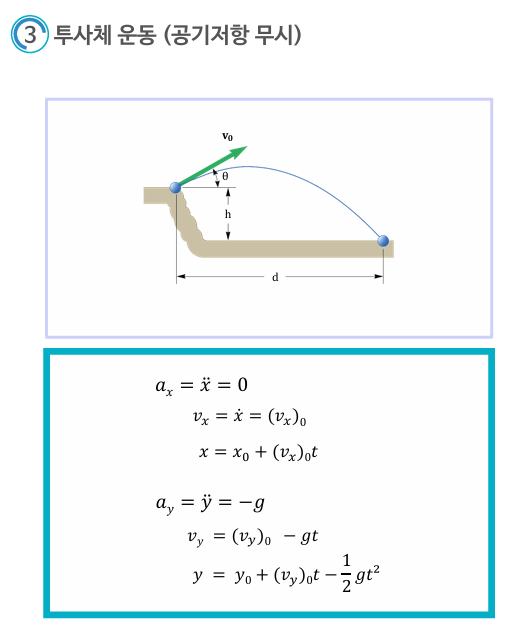

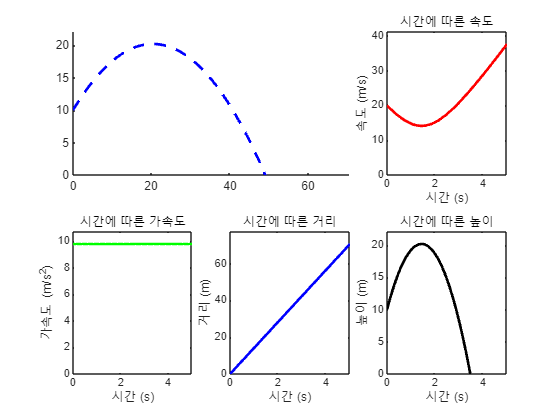

% 초기 값 설정
v0 = 20;  % 초기 속도 (m/s)
theta = 45;  % 발사각 (도)
g = 9.81;  % 중력 가속도 (m/s^2)
h = 10;  % 초기 높이 (m)

% 발사각을 라디안으로 변환
theta_rad = deg2rad(theta);

% 초기 속도의 x와 y 성분
vx0 = v0 * cos(theta_rad);  % 수평 속도 성분
vy0 = v0 * sin(theta_rad);  % 수직 속도 성분

% 시간 벡터 생성
t = linspace(0, 5, 100);  % 0초에서 5초까지 100개의 시간 값

% 시간에 따른 x(t)와 y(t) 계산
x_t = vx0 * t;  % 수평 위치
y_t = h + vy0 * t - (1/2) * g * t.^2;  % 수직 위치

% 속도 계산 (속도는 속도의 크기이므로 피타고라스 정리 이용)
v_t = sqrt(vx0^2 + (vy0 - g * t).^2);

% 가속도 (y방향 가속도는 중력 가속도)
a_x = zeros(size(t));  % 수평 가속도는 0 (등속)
a_y = -g * ones(size(t));  % 수직 가속도는 중력 가속도

% 총 가속도 크기
a_t = sqrt(a_x.^2 + a_y.^2);

% 애니메이션 준비
figure;

% 서브플롯을 사용하여 메인 애니메이션 및 동적 그래프 추가
subplot(2, 3, [1 2]);  % 2행 3열 중 첫 번째와 두 번째를 메인 애니메이션으로 사용
hold on;
xlim([0 max(x_t)]);
ylim([0 max(y_t) + 2]);

% 경로 그리기
plot(x_t, y_t, 'b--', 'LineWidth', 2);

% 공 그래픽 생성
ball = rectangle('Position', [x_t(1)-1.25, y_t(1)-1.25, 2.5, 2.5], 'Curvature', [1, 1], 'FaceColor', 'r');

% 1. 속도 그래프 (시간에 따른 속도)
subplot(2, 3, 3);
h_velocity = plot(t(1), v_t(1), 'r', 'LineWidth', 2);
xlim([0 max(t)]);
ylim([0 max(v_t) * 1.1]);
xlabel('시간 (s)');
ylabel('속도 (m/s)');
title('시간에 따른 속도');

% 2. 가속도 그래프 (시간에 따른 가속도)
subplot(2, 3, 4);
h_acceleration = plot(t(1), a_t(1), 'g', 'LineWidth', 2);
xlim([0 max(t)]);
ylim([0 max(a_t) * 1.1]);
xlabel('시간 (s)');
ylabel('가속도 (m/s^2)');
title('시간에 따른 가속도');

% 3. 거리 그래프 (시간에 따른 거리)
subplot(2, 3, 5);
h_distance = plot(t(1), x_t(1), 'b', 'LineWidth', 2);
xlim([0 max(t)]);
ylim([0 max(x_t) * 1.1]);
xlabel('시간 (s)');
ylabel('거리 (m)');
title('시간에 따른 거리');

% 4. 높이 그래프 (시간에 따른 높이)
subplot(2, 3, 6);
h_height = plot(t(1), y_t(1), 'k', 'LineWidth', 2);
xlim([0 max(t)]);
ylim([0 max(y_t) * 1.1]);
xlabel('시간 (s)');
ylabel('높이 (m)');
title('시간에 따른 높이');

% 애니메이션 루프
for i = 1:length(t)
    % 메인 애니메이션 (공 위치 업데이트)
    subplot(2, 3, [1 2]);
    set(ball, 'Position', [x_t(i)-1.25, y_t(i)-1.25, 2.5, 2.5]);  % 공 위치 업데이트
    
    % 1. 속도 그래프 업데이트
    subplot(2, 3, 3);
    set(h_velocity, 'XData', t(1:i), 'YData', v_t(1:i));  % 속도 그래프 업데이트
    
    % 2. 가속도 그래프 업데이트
    subplot(2, 3, 4);
    set(h_acceleration, 'XData', t(1:i), 'YData', a_t(1:i));  % 가속도 그래프 업데이트
    
    % 3. 거리 그래프 업데이트
    subplot(2, 3, 5);
    set(h_distance, 'XData', t(1:i), 'YData', x_t(1:i));  % 거리 그래프 업데이트
    
    % 4. 높이 그래프 업데이트
    subplot(2, 3, 6);
    set(h_height, 'XData', t(1:i), 'YData', y_t(1:i));  % 높이 그래프 업데이트
    
    % 화면 강제 갱신
    drawnow;
    
    % 애니메이션 속도 조절
    pause(0.05);
end

hold off;

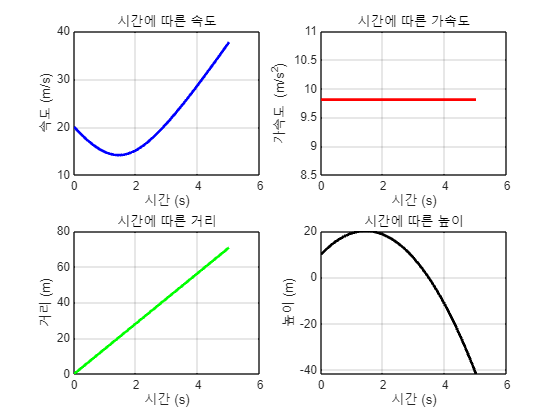

% 초기 값 설정
v0 = 20;  % 초기 속도 (m/s)
theta = 45;  % 발사각 (도)
g = 9.81;  % 중력 가속도 (m/s^2)
h = 10;  % 초기 높이 (m)

% 발사각을 라디안으로 변환
theta_rad = deg2rad(theta);

% 초기 속도의 x와 y 성분
vx0 = v0 * cos(theta_rad);  % 수평 속도 성분
vy0 = v0 * sin(theta_rad);  % 수직 속도 성분

% 시간 벡터 생성
t = linspace(0, 5, 100);  % 0초에서 5초까지 100개의 시간 값

% 시간에 따른 x(t)와 y(t) 계산
x_t = vx0 * t;  % 수평 위치
y_t = h + vy0 * t - (1/2) * g * t.^2;  % 수직 위치

% 속도 계산 (속도는 속도의 크기이므로 피타고라스 정리 이용)
v_t = sqrt(vx0^2 + (vy0 - g * t).^2);

% 가속도 (y방향 가속도는 중력 가속도)
a_x = zeros(size(t));  % 수평 가속도는 0 (등속)
a_y = -g * ones(size(t));  % 수직 가속도는 중력 가속도

% 총 가속도 크기
a_t = sqrt(a_x.^2 + a_y.^2);

% 그래프를 4개 그리기
figure;

% 1. 시간에 따른 속도 그래프
subplot(2, 2, 1);
plot(t, v_t, 'b', 'LineWidth', 2);
xlabel('시간 (s)');
ylabel('속도 (m/s)');
title('시간에 따른 속도');
grid on;

% 2. 시간에 따른 가속도 그래프
subplot(2, 2, 2);
plot(t, a_t, 'r', 'LineWidth', 2);
xlabel('시간 (s)');
ylabel('가속도 (m/s^2)');
title('시간에 따른 가속도');
grid on;

% 3. 시간에 따른 거리(수평 위치) 그래프
subplot(2, 2, 3);
plot(t, x_t, 'g', 'LineWidth', 2);
xlabel('시간 (s)');
ylabel('거리 (m)');
title('시간에 따른 거리');
grid on;

% 4. 시간에 따른 높이(수직 위치) 그래프
subplot(2, 2, 4);
plot(t, y_t, 'k', 'LineWidth', 2);
xlabel('시간 (s)');
ylabel('높이 (m)');
title('시간에 따른 높이');
grid on;

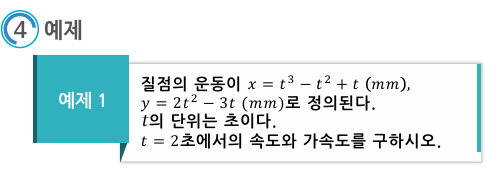

% 주어진 t에서의 속도와 가속도 계산
t = 2;  % 시간 t = 2초

% x(t)와 y(t) 방정식 정의
x_t = @(t) t.^3 - t.^2 + t;  % x = t^3 - t^2 + t (mm)
y_t = @(t) 2*t.^2 - 3*t;     % y = 2t^2 - 3t (mm)

% x(t)와 y(t)의 1차 미분 (속도)
vx_t = @(t) 3*t.^2 - 2*t + 1;  % vx = dx/dt
vy_t = @(t) 4*t - 3;           % vy = dy/dt

% x(t)와 y(t)의 2차 미분 (가속도)
ax_t = @(t) 6*t - 2;  % ax = d(vx)/dt
ay_t = @(t) 4;        % ay = d(vy)/dt

% t = 2에서의 속도와 가속도 계산
vx_2 = vx_t(t);
vy_2 = vy_t(t);
ax_2 = ax_t(t);
ay_2 = ay_t(t);

% 속력 계산
v_2 = sqrt(vx_2^2 + vy_2^2);  % v = sqrt(vx^2 + vy^2)

% 이동 각도 계산 (tan(theta) = vy/vx)
theta_2 = atan2(vy_2, vx_2) * 180 / pi;  % 각도 (도 단위)

% 결과 출력
fprintf('t = %.1f초에서의 속도 (vx, vy): %.2f mm/s, %.2f mm/s\n', t, vx_2, vy_2);

t = 2.0초에서의 속도 (vx, vy): 9.00 mm/s, 5.00 mm/s


fprintf('t = %.1f초에서의 가속도 (ax, ay): %.2f mm/s^2, %.2f mm/s^2\n', t, ax_2, ay_2);

t = 2.0초에서의 가속도 (ax, ay): 10.00 mm/s^2, 4.00 mm/s^2


fprintf('t = %.1f초에서의 속력: %.2f mm/s\n', t, v_2);

t = 2.0초에서의 속력: 10.30 mm/s


fprintf('t = %.1f초에서의 이동 각도 θ: %.2f 도\n', t, theta_2);

t = 2.0초에서의 이동 각도 θ: 29.05 도


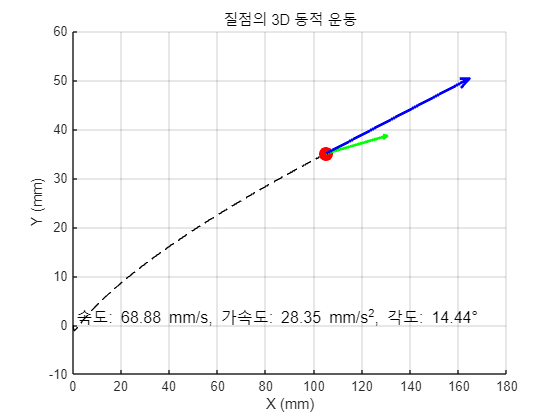

% 심볼릭 변수 선언
syms t

% 주어진 위치 함수
x = t^3 - t^2 + t;  % x(t) in mm
y = 2*t^2 - 3*t;    % y(t) in mm
z = t^2;            % z(t) 추가로 3차원으로 만듭니다 (임의의 z축 함수)

% 속도 함수 구하기 (위치의 1차 미분)
vx = diff(x, t);
vy = diff(y, t);
vz = diff(z, t);

% 가속도 함수 구하기 (속도의 1차 미분)
ax = diff(vx, t);
ay = diff(vy, t);
az = diff(vz, t);

% t = 0부터 5초까지 시간 설정
t_vals = linspace(0, 5, 100);  % 시간 벡터

% 위치, 속도, 가속도 계산
x_vals = double(subs(x, t, t_vals));
y_vals = double(subs(y, t, t_vals));
z_vals = double(subs(z, t, t_vals));

vx_vals = double(subs(vx, t, t_vals));
vy_vals = double(subs(vy, t, t_vals));
vz_vals = double(subs(vz, t, t_vals));

ax_vals = double(subs(ax, t, t_vals));
ay_vals = double(subs(ay, t, t_vals));
az_vals = double(subs(az, t, t_vals));

% 속도 및 가속도의 크기 계산
speed_vals = sqrt(vx_vals.^2 + vy_vals.^2 + vz_vals.^2);  % 속도의 크기
acceleration_vals = sqrt(ax_vals.^2 + ay_vals.^2 + az_vals.^2);  % 가속도의 크기

% tan θ 계산 (vy/vx)
theta_vals = atan2(vy_vals, vx_vals) * (180 / pi);  % 각도 (도 단위)

% 3D 애니메이션 준비
figure;
hold on;
grid on;
xlabel('X (mm)');
ylabel('Y (mm)');
zlabel('Z (mm)');
title('질점의 3D 동적 운동');

% 공 그래픽 생성
ball = plot3(x_vals(1), y_vals(1), z_vals(1), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% 속도 및 가속도 벡터 생성
velocity_arrow = quiver3(x_vals(1), y_vals(1), z_vals(1), vx_vals(1), vy_vals(1), vz_vals(1), 'b', 'LineWidth', 2);
acceleration_arrow = quiver3(x_vals(1), y_vals(1), z_vals(1), ax_vals(1), ay_vals(1), az_vals(1), 'g', 'LineWidth', 2);

% 텍스트 추가 (속도, 가속도, 각도)
info_text = text(1, 1.5, 1.5, sprintf('속도: %.2f mm/s, 가속도: %.2f mm/s^2, 각도: %.2f°', speed_vals(1), acceleration_vals(1), theta_vals(1)), 'FontSize', 12, 'Color', 'k');

% 궤적 그리기
trajectory = plot3(x_vals, y_vals, z_vals, 'k--');

% 애니메이션 루프
for i = 1:length(t_vals)
    % 공 위치 업데이트
    set(ball, 'XData', x_vals(i), 'YData', y_vals(i), 'ZData', z_vals(i));
    
    % 속도 벡터 업데이트
    set(velocity_arrow, 'XData', x_vals(i), 'YData', y_vals(i), 'ZData', z_vals(i), ...
        'UData', vx_vals(i), 'VData', vy_vals(i), 'WData', vz_vals(i));
    
    % 가속도 벡터 업데이트
    set(acceleration_arrow, 'XData', x_vals(i), 'YData', y_vals(i), 'ZData', z_vals(i), ...
        'UData', ax_vals(i), 'VData', ay_vals(i), 'WData', az_vals(i));
    
    % 텍스트 업데이트 (속도, 가속도, 각도)
    set(info_text, 'String', sprintf('속도: %.2f mm/s, 가속도: %.2f mm/s^2, 각도: %.2f°', speed_vals(i), acceleration_vals(i), theta_vals(i)));
    
    % 화면 갱신
    drawnow;
    pause(0.05);  % 애니메이션 속도 조절
end

hold off;

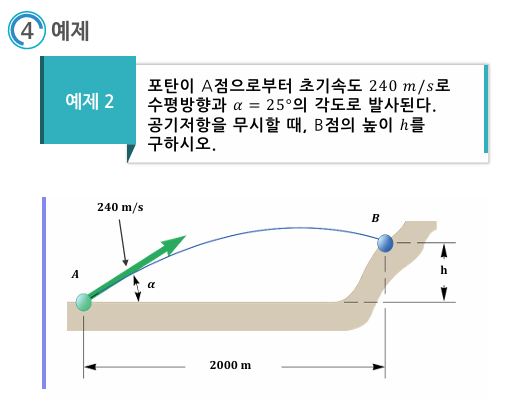

% 주어진 값
v0 = 240;  % 초기 속도 (m/s)
alpha = 25;  % 각도 (도)
g = 9.81;  % 중력 가속도 (m/s^2)
d = 2000;  % A점에서 B점까지의 수평 거리 (m)

% 각도를 라디안으로 변환
alpha_rad = deg2rad(alpha);

% 초기 속도의 수평 및 수직 성분 계산
v0_x = v0 * cos(alpha_rad);  % 수평 속도 성분 (m/s)
v0_y = v0 * sin(alpha_rad);  % 수직 속도 성분 (m/s)

% B점에서의 시간을 계산 (수평 거리만 이용)
t_B = d / v0_x;  % 수평 이동 시간

% B점에서의 높이 h 계산
h_B = v0_y * t_B - (1/2) * g * t_B^2;  % B점에서의 높이

% 결과 출력
fprintf('B점에서의 시간 t: %.2f 초\n', t_B);

B점에서의 시간 t: 9.19 초


fprintf('B점에서의 높이 h: %.2f m\n', h_B);

B점에서의 높이 h: 517.92 m


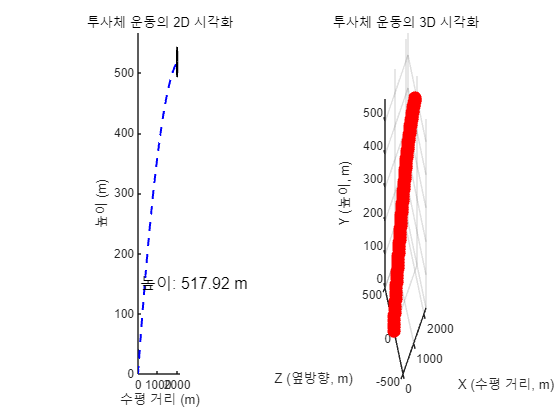


% 시간을 100개로 나누기
t_vals = linspace(0, t_B, 100);

% 포물선 궤적 계산
x_vals = v0_x * t_vals;  % 수평 거리
y_vals = v0_y * t_vals - (1/2) * g * t_vals.^2;  % 높이

%% 2D 애니메이션

figure;
subplot(1,2,1);  % 2D 애니메이션
hold on;
xlim([0, d + 200]);
ylim([0, max(y_vals)+50]);

% 포물선 궤적 그리기
plot(x_vals, y_vals, 'b--', 'LineWidth', 1.5);
title('투사체 운동의 2D 시각화');
xlabel('수평 거리 (m)');
ylabel('높이 (m)');

% 공 그래픽 생성
ball = rectangle('Position', [x_vals(1), y_vals(1), 50, 50], 'Curvature', [1, 1], 'FaceColor', 'r');

% 텍스트 정보
info_text = text(100, 150, sprintf('높이: %.2f m', y_vals(1)), 'FontSize', 12, 'Color', 'k');

% 애니메이션 루프
for i = 1:length(t_vals)
    % 공 위치 업데이트
    set(ball, 'Position', [x_vals(i)-25, y_vals(i)-25, 50, 50]);  % 공 크기 변경
    
    % 텍스트 업데이트
    set(info_text, 'String', sprintf('높이: %.2f m', y_vals(i)));
    
    % 화면 강제 갱신
    drawnow;
    
    pause(0.05);  % 애니메이션 속도 조절
end
hold off;

%% 3D 시각화
subplot(1,2,2);  % 3D 시각화
hold on;

z_vals = zeros(size(x_vals));  % z축 값은 0으로 설정 (2D 움직임이므로)

% 3D 궤적 그리기
plot3(x_vals, z_vals, y_vals, 'r-', 'LineWidth', 2);

% 축 설정
xlim([0, d + 200]);
ylim([-500, 500]);
zlim([0, max(y_vals)+50]);
xlabel('X (수평 거리, m)');
ylabel('Z (옆방향, m)');
zlabel('Y (높이, m)');
title('투사체 운동의 3D 시각화');

% 그래프 회전 모드 활성화
view(3);  % 3D 보기
grid on;

% 3D 공의 위치
scatter3(x_vals(1), z_vals(1), y_vals(1), 100, 'filled', 'r');

% 애니메이션 루프 (3D에서 공의 궤적 따라가기)
for i = 1:length(t_vals)
    scatter3(x_vals(i), z_vals(i), y_vals(i), 100, 'filled', 'r');  % 공 크기 설정
    drawnow;
    pause(0.05);
end
hold off;

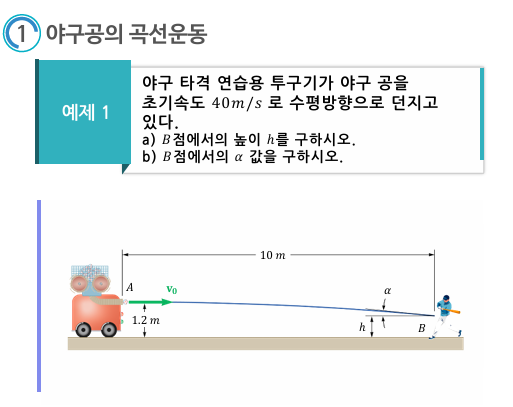

% 주어진 값
v0 = 40;  % 초기 속도 (m/s)
g = 9.81;  % 중력 가속도 (m/s^2)
x_B = 10;  % A에서 B까지의 수평 거리 (m)
y0 = 1.2;  % 초기 높이 (m)

% a) B점에서의 높이 h 계산
t_B = x_B / v0;  % B점까지 도달하는 시간
h_B = y0 - (1/2) * g * t_B^2;  % B점에서의 높이

% b) B점에서의 각도 alpha 계산
vy_B = -g * t_B;  % B점에서의 수직 속도
vx_B = v0;        % 수평 속도는 일정
alpha_B = atan2(vy_B, vx_B) * 180 / pi;  % 각도 (도 단위)

% 결과 출력
fprintf('B점까지 도달하는 시간 t: %.2f 초\n', t_B);

B점까지 도달하는 시간 t: 0.25 초


fprintf('B점에서의 높이 h: %.2f m\n', h_B);

B점에서의 높이 h: 0.89 m


fprintf('B점에서의 각도 alpha: %.2f 도\n', alpha_B);

B점에서의 각도 alpha: -3.51 도


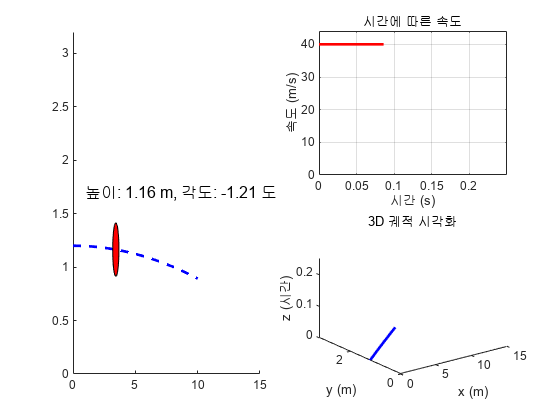


% 시간 설정
t_vals = linspace(0, t_B, 100);

% 궤적 계산
x_vals = v0 * t_vals;  % 수평 거리
y_vals = y0 - (1/2) * g * t_vals.^2;  % 높이

% 수직 속도 계산
vy_vals = -g * t_vals;  % 시간에 따른 수직 속도
v_vals = sqrt(v0^2 + vy_vals.^2);  % 총 속도 계산
alpha_vals = atan2(vy_vals, v0) * 180 / pi;  % 시간에 따른 각도 계산

% 애니메이션 준비
figure;

% 첫 번째 그래프: 2D 애니메이션
subplot(2, 2, [1, 3]);  % 왼쪽 큰 영역에 애니메이션
hold on;
xlim([0, x_B + 5]);  % x축 범위
ylim([0, y0 + 2]);  % y축 범위

% 포물선 궤적 그리기
plot(x_vals, y_vals, 'b--', 'LineWidth', 2);

% 공 그래픽 생성
ball = rectangle('Position', [x_vals(1), y_vals(1), 0.5, 0.5], 'Curvature', [1, 1], 'FaceColor', 'r');

% 높이 및 각도 정보 텍스트 추가
info_text = text(1, y0 + 0.5, sprintf('높이: %.2f m, 각도: %.2f 도', y0, alpha_vals(1)), 'FontSize', 12, 'Color', 'k');

% 두 번째 그래프: 속도 동적 그래프
subplot(2, 2, 2);  % 상단 우측
h_velocity = plot(t_vals(1), v_vals(1), 'r', 'LineWidth', 2);  % 초기값 설정
xlim([0, t_B]);
ylim([0, max(v_vals) * 1.1]);  % 속도 그래프의 y축 범위 설정
xlabel('시간 (s)');
ylabel('속도 (m/s)');
title('시간에 따른 속도');
grid on;

% 세 번째 그래프: 3D 궤적 시각화
subplot(2, 2, 4);  % 하단 우측
hold on;
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (시간)');
title('3D 궤적 시각화');
view(3);  % 3D 뷰 설정
xlim([0, x_B + 5]);
ylim([0, y0 + 2]);
zlim([0, t_B]);
h_3d = plot3(x_vals(1), y_vals(1), t_vals(1), 'b', 'LineWidth', 2);  % 초기 3D 그래프

% 애니메이션 루프
for i = 1:length(t_vals)
    % 공 위치 업데이트
    set(ball, 'Position', [x_vals(i)-0.25, y_vals(i)-0.25, 0.5, 0.5]);  % 공 위치 업데이트
    
    % 텍스트 업데이트 (높이 및 각도)
    set(info_text, 'String', sprintf('높이: %.2f m, 각도: %.2f 도', y_vals(i), alpha_vals(i)));
    
    % 속도 그래프 업데이트
    set(h_velocity, 'XData', t_vals(1:i), 'YData', v_vals(1:i));  % 속도 그래프 업데이트
    
    % 3D 그래프 업데이트
    set(h_3d, 'XData', x_vals(1:i), 'YData', y_vals(1:i), 'ZData', t_vals(1:i));  % 3D 궤적 업데이트
    
    % 화면 강제 갱신
    drawnow;
    
    pause(0.05);  % 애니메이션 속도 조절
end


hold off;


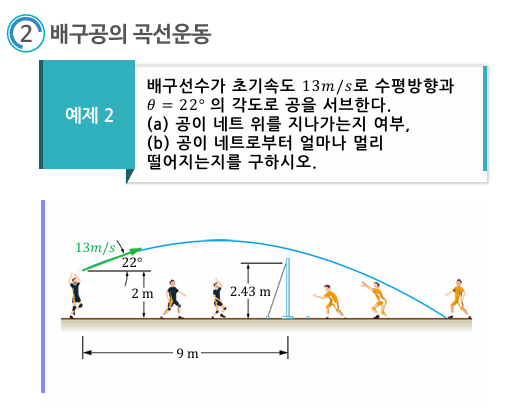

**주어진 값:**

- 초기 속도 $v_0 = 13 \, \text{m/s}$

- 발사 각도 $\theta = 22^\circ$

- 중력 가속도$g = 9.81 \, \text{m/s}^2$

- 네트의 높이 $h_\text{net} = 2.43 \, \text{m}$

- 네트와 선수 사이의 거리는 $9 \, \text{m}$

% 주어진 값
v0 = 13;  % 초기 속도 (m/s)
theta = 22;  % 발사 각도 (도)
g = 9.81;  % 중력 가속도 (m/s^2)
h_net = 2.43;  % 네트의 높이 (m)
distance_net = 9;  % 네트까지의 거리 (m)
y0 = 2;  % 초기 높이 (m)

% 각도를 라디안으로 변환
theta_rad = deg2rad(theta);

% 초기 속도의 수평 및 수직 성분
vx0 = v0 * cos(theta_rad);
vy0 = v0 * sin(theta_rad);

% 공이 네트 위를 지나는지 확인하기 위해 네트 지점에서의 시간 계산
t_net = distance_net / vx0;

% 공이 네트 지점에서의 높이 계산
y_net = y0 + vy0 * t_net - 0.5 * g * t_net^2;

fprintf('네트까지 도달하는 시간 t: %.2f 초\n', t_net);

네트까지 도달하는 시간 t: 0.75 초


fprintf('네트지점에서의 높이 h: %.2f m\n', y_net);

네트지점에서의 높이 h: 2.90 m



% 공이 네트를 넘는지 여부 출력
if y_net > h_net
    fprintf('공이 네트를 %.2f m 위로 넘습니다.\n', y_net - h_net);
else
    fprintf('공이 네트에 걸렸습니다. %.2f m 아래입니다.\n', h_net - y_net);
end

공이 네트를 0.47 m 위로 넘습니다.



% 공의 총 비행 시간 계산 (착지 지점에서 y_B = 0일 때)
t_B = (vy0 + sqrt(vy0^2 + 2 * g * y0)) / g;

% 착지 지점까지의 수평 거리 계산
x_land = vx0 * t_B;

% 네트로부터 착지 지점까지의 거리
distance_from_net = x_land - distance_net;

% 결과 출력
fprintf('공이 지면에 도달하는 시간 t: %.2f 초\n', t_B);

공이 지면에 도달하는 시간 t: 1.31 초


fprintf('공이 출발지점에서 지면에 도달한 거리 d: %.2f m\n', x_land);

공이 출발지점에서 지면에 도달한 거리 d: 15.73 m


fprintf('공의 착지 지점은 네트로부터 %.2f m 떨어진 위치입니다.\n', distance_from_net);

공의 착지 지점은 네트로부터 6.73 m 떨어진 위치입니다.


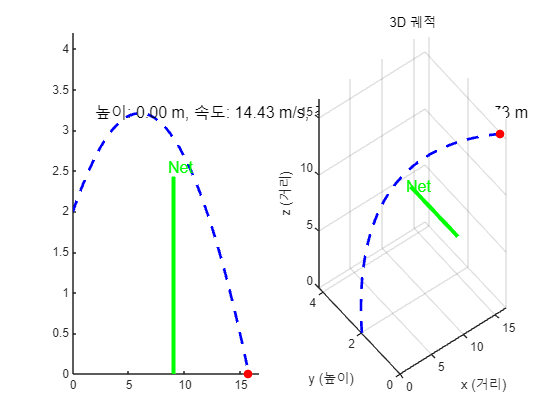


% 애니메이션 준비
figure;

% 공의 궤적 그리기 (2D 그래프)
t_vals = linspace(0, t_B, 100);
x_vals = vx0 * t_vals;  % 수평 위치
y_vals = y0 + vy0 * t_vals - 0.5 * g * t_vals.^2;  % 수직 위치

% 3D 그래프 추가 (Z축을 수평축과 동일하게 사용하여 시각화)
z_vals = x_vals;  % Z축 추가 (동일한 값 사용)

% 애니메이션 생성
subplot(1, 2, 1); % 2D 애니메이션
hold on;
xlim([0, x_land + 1]);  % x축 범위 설정
ylim([0, max(y_vals) + 1]);  % y축 범위 설정
plot(x_vals, y_vals, 'b--', 'LineWidth', 2);  % 포물선 궤적
ball = plot(x_vals(1), y_vals(1), 'ro', 'MarkerFaceColor', 'r');  % 공 그래픽 생성

% 네트 위치 표시
plot([distance_net, distance_net], [0, h_net], 'g-', 'LineWidth', 3);  % 네트의 위치 (수직선)
text(distance_net - 0.5, h_net + 0.1, 'Net', 'FontSize', 12, 'Color', 'g');  % 네트 라벨

% 텍스트로 높이, 속도, 각도, 거리 정보 표시
info_text = text(2, max(y_vals), sprintf('높이: %.2f m, 각도: %.2f도', y0, theta), 'FontSize', 12, 'Color', 'k');

% 3D 그래프 생성
subplot(1, 2, 2);
h_3d = plot3(x_vals(1), y_vals(1), z_vals(1), 'ro', 'MarkerFaceColor', 'r');
hold on;
grid on;
plot3(x_vals, y_vals, z_vals, 'b--', 'LineWidth', 2);  % 3D 궤적
xlim([0, x_land + 1]);
ylim([0, max(y_vals) + 1]);
zlim([0, x_land + 1]);
xlabel('x (거리)');
ylabel('y (높이)');
zlabel('z (거리)');
title('3D 궤적');

% 네트 위치 3D 표시
plot3([distance_net, distance_net], [0, h_net], [distance_net, distance_net], 'g-', 'LineWidth', 3);  % 네트 3D 위치
text(distance_net - 0.5, h_net + 0.1, distance_net, 'Net', 'FontSize', 12, 'Color', 'g');  % 네트 라벨

% 애니메이션 실행
for i = 1:length(t_vals)
    % 공의 위치 업데이트
    set(ball, 'XData', x_vals(i), 'YData', y_vals(i));
    set(h_3d, 'XData', x_vals(i), 'YData', y_vals(i), 'ZData', z_vals(i));
    
    % 텍스트 업데이트 (높이, 속도, 각도)
    v = sqrt(vx0^2 + (vy0 - g * t_vals(i))^2);  % 속도 계산
    angle = atan2(vy0 - g * t_vals(i), vx0) * 180 / pi;  % 각도 계산
    distance = x_vals(i);  % 거리 계산
    set(info_text, 'String', sprintf('높이: %.2f m, 속도: %.2f m/s, 각도: %.2f 도, 거리: %.2f m', y_vals(i), v, angle, distance));
    
    % 화면 갱신
    drawnow;
    pause(0.05);
end

hold off;

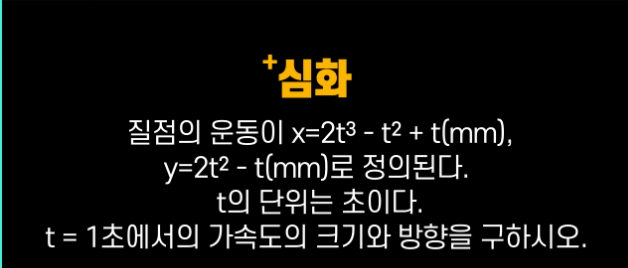

**문제 분석:**

- **주어진 위치 함수**:

- $x(t) = 2t^3 - t^2 + t\$(단위: mm)

- $y(t) = 2t^2 - t$ (단위: mm)

- **속도 및 가속도 구하기**:

- 속도는 위치의 1차 미분.

- 가속도는 속도의 1차 미분.

**계산 방법:**

- $v_x(t) = \frac{dx}{dt}$�

- $v_y(t) = \frac{dy}{dt}$�

- $a_x(t) = \frac{dv_x}{dt}$��

- $a_y(t) = \frac{dv_y}{dt}$��

가속도의 크기 $|a(t)|$는 $a_x^2 + a_y^2$�의 제곱근으로 구할 수 있으며, 방향(각도)은 $\tan^{-1}(a_y / a_x)$로 구할 수 있습니다.

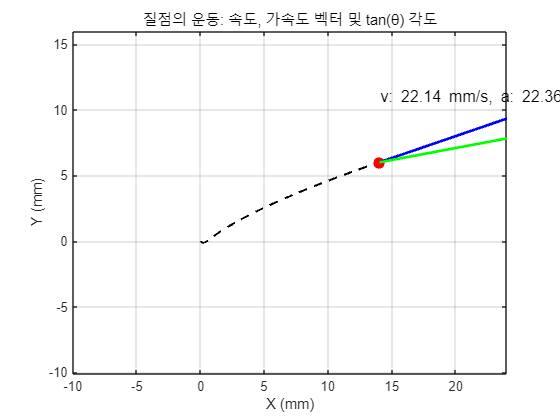

% 심볼릭 변수 선언
syms t

% 주어진 위치 함수
x = 2*t^3 - t^2 + t;  % x(t) in mm
y = 2*t^2 - t;        % y(t) in mm

% 속도 함수 구하기 (위치의 1차 미분)
vx = diff(x, t);
vy = diff(y, t);

% 가속도 함수 구하기 (속도의 1차 미분)
ax = diff(vx, t);
ay = diff(vy, t);

% 시간 값 설정
t_vals = linspace(0, 2, 100);  % t = 0초에서 2초까지
x_vals = double(subs(x, t, t_vals));  % x(t) 값
y_vals = double(subs(y, t, t_vals));  % y(t) 값

% 속도 및 가속도 벡터 계산
vx_vals = double(subs(vx, t, t_vals));  % vx(t)
vy_vals = double(subs(vy, t, t_vals));  % vy(t)
ax_vals = double(subs(ax, t, t_vals));  % ax(t)
ay_vals = double(subs(ay, t, t_vals));  % ay(t)

% 속도 크기 및 각도 계산
v_vals = sqrt(vx_vals.^2 + vy_vals.^2);  % 속도 크기
a_vals = sqrt(ax_vals.^2 + ay_vals.^2);  % 가속도 크기
theta_vals = atan2(vy_vals, vx_vals) * 180 / pi;  % 각도 (도 단위)

% 초기 플롯 설정
figure;
h_traj = plot(x_vals, y_vals, 'k--', 'LineWidth', 1.5);  % 궤적
hold on;
h_point = plot(x_vals(1), y_vals(1), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');  % 공의 초기 위치

% 속도, 가속도 벡터 표시 (초기화)
h_velocity = quiver(x_vals(1), y_vals(1), vx_vals(1), vy_vals(1), 'b', 'LineWidth', 2);
h_acceleration = quiver(x_vals(1), y_vals(1), ax_vals(1), ay_vals(1), 'g', 'LineWidth', 2);

% 각도 및 속도, 가속도 정보 텍스트 추가
info_text = text(x_vals(1), y_vals(1)+5, sprintf('v: %.2f mm/s, a: %.2f mm/s^2, θ: %.2f°', v_vals(1), a_vals(1), theta_vals(1)), 'FontSize', 12, 'Color', 'k');

% 플롯의 속성 설정
xlabel('X (mm)');
ylabel('Y (mm)');
title('질점의 운동: 속도, 가속도 벡터 및 tan(θ) 각도');
grid on;
xlim([min(x_vals)-10, max(x_vals)+10]);
ylim([min(y_vals)-10, max(y_vals)+10]);

% 애니메이션 루프
for i = 1:length(t_vals)
    % 공의 위치 업데이트
    set(h_point, 'XData', x_vals(i), 'YData', y_vals(i));
    
    % 속도 벡터 업데이트
    set(h_velocity, 'XData', x_vals(i), 'YData', y_vals(i), ...
        'UData', vx_vals(i), 'VData', vy_vals(i));  % 속도 벡터
    
    % 가속도 벡터 업데이트
    set(h_acceleration, 'XData', x_vals(i), 'YData', y_vals(i), ...
        'UData', ax_vals(i), 'VData', ay_vals(i));  % 가속도 벡터
    
    % 텍스트 업데이트 (속도, 가속도, 각도 정보)
    set(info_text, 'Position', [x_vals(i), y_vals(i)+5], ...
        'String', sprintf('v: %.2f mm/s, a: %.2f mm/s^2, θ: %.2f°', v_vals(i), a_vals(i), theta_vals(i)));
    
    % 화면 갱신
    drawnow;
    
    pause(0.05);  % 애니메이션 속도 조절
end

hold off;

% 심볼릭 변수 선언
syms t

% 주어진 위치 함수
x = 2*t^3 - t^2 + t;  % x(t) in mm
y = 2*t^2 - t;        % y(t) in mm

% 속도 함수 구하기 (위치의 1차 미분)
vx = diff(x, t);
vy = diff(y, t);

% 가속도 함수 구하기 (속도의 1차 미분)
ax = diff(vx, t);
ay = diff(vy, t);

% t = 1에서 가속도 계산
t_val = 1;  % 1초
ax_val = double(subs(ax, t, t_val));
ay_val = double(subs(ay, t, t_val));

% 가속도의 크기 계산
a_magnitude = sqrt(ax_val^2 + ay_val^2);

% 가속도의 방향 계산 (각도)
a_angle = atan2(ay_val, ax_val) * (180 / pi);  % 라디안을 도(degree)로 변환

% 결과 출력
fprintf('t = %.1f 초에서의 가속도의 크기: %.2f mm/s^2\n', t_val, a_magnitude);

t = 1.0 초에서의 가속도의 크기: 10.77 mm/s^2


fprintf('t = %.1f 초에서의 가속도의 방향: %.2f 도\n', t_val, a_angle);

t = 1.0 초에서의 가속도의 방향: 21.80 도


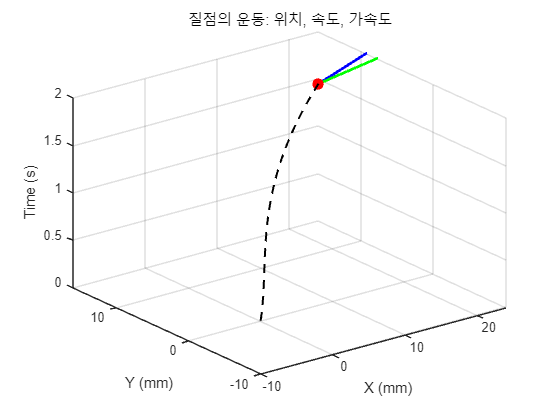


% 시간 값 설정
t_vals = linspace(0, 2, 100);  % t = 0초에서 2초까지
x_vals = double(subs(x, t, t_vals));  % x(t) 값
y_vals = double(subs(y, t, t_vals));  % y(t) 값

% 속도 및 가속도 벡터 계산
vx_vals = double(subs(vx, t, t_vals));  % vx(t)
vy_vals = double(subs(vy, t, t_vals));  % vy(t)
ax_vals = double(subs(ax, t, t_vals));  % ax(t)
ay_vals = double(subs(ay, t, t_vals));  % ay(t)

% 초기 플롯 설정
figure;
h_traj = plot3(x_vals, y_vals, t_vals, 'k--', 'LineWidth', 1.5);  % 궤적
hold on;
h_point = plot3(x_vals(1), y_vals(1), t_vals(1), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');  % 공의 초기 위치

% 속도, 가속도 벡터 표시 (초기화)
h_velocity = quiver3(x_vals(1), y_vals(1), t_vals(1), vx_vals(1), vy_vals(1), 0, 'b', 'LineWidth', 2);
h_acceleration = quiver3(x_vals(1), y_vals(1), t_vals(1), ax_vals(1), ay_vals(1), 0, 'g', 'LineWidth', 2);

% 플롯의 속성 설정
xlabel('X (mm)');
ylabel('Y (mm)');
zlabel('Time (s)');
title('질점의 운동: 위치, 속도, 가속도');
grid on;
xlim([min(x_vals)-10, max(x_vals)+10]);
ylim([min(y_vals)-10, max(y_vals)+10]);
zlim([0, 2]);

% 애니메이션 루프
for i = 1:length(t_vals)
    % 공의 위치 업데이트
    set(h_point, 'XData', x_vals(i), 'YData', y_vals(i), 'ZData', t_vals(i));
    
    % 속도 벡터 업데이트
    set(h_velocity, 'XData', x_vals(i), 'YData', y_vals(i), 'ZData', t_vals(i), ...
        'UData', vx_vals(i), 'VData', vy_vals(i), 'WData', 0);  % 속도는 시간 축에 없음
    
    % 가속도 벡터 업데이트
    set(h_acceleration, 'XData', x_vals(i), 'YData', y_vals(i), 'ZData', t_vals(i), ...
        'UData', ax_vals(i), 'VData', ay_vals(i), 'WData', 0);  % 가속도도 시간 축에 없음
    
    % 화면 갱신
    drawnow;
    
    pause(0.05);  % 애니메이션 속도 조절
end